## Runge's phenomenon: when neither least squares fitting nor interpolation succeed...

clearvars
close all

Consider the function


$$$$
f(x) = \frac{1}{1+ 25 x^{2}},
$$$$


in the interval $I=[-1,1]$, and a sample of N=11 equispaced nodes of its values, $x_{i} = -1+0.2(i-1)$, $i=1,2,\dots,N$.  

r=25.0;
f = @(x) 1./(1+r*x.^2);

a=-1;
b = 1;
x = a:0.2:b;
y = f(x);

xOrig=a:0.01:b;
yOrig=f(xOrig);
n = size(x,2);

degree = [3,5,7,10];
numPlots = size(degree,2);


### Least Square Fitting and Interpolation

Compute and plot the LSF (Least Square Fit) polynomials of degree 3, 5, 7 and the inperpolation polynomial (of degree 10).

figure()
for k = 1:size(degree,2)
    p = polyfit(x,y,degree(k));
    yyy = polyval(p,xOrig);
    subplot(3,2,k);
    plot(x,y,'o','Marker','o','MarkerFaceColor','red','MarkerEdgeColor',...
        'black','lineWidth',1)
    hold on
    plot(xOrig,yOrig,'-','color','black')
    plot(xOrig,yyy,'-','color','blue')
    xlabel('$x$','Interpreter','LaTeX')
    ylabel('$y$','Interpreter','LaTeX')
    if degree(k) < n - 1
        title(['LSF polynomial of deg. ', num2str(degree(k))],...
            'interpreter','LaTeX')
    else
        title(['Interp. polynomial of deg. ', num2str(degree(k))],...
            'interpreter','LaTeX')
    end
    ymax = max([yOrig,yyy]);
    ymin = min([yOrig,yyy]);
    axis([-1,1,ymin,ymax])
    hold off
end


### Linar Splines (polygonal approximation)

xp = a:0.1:b;
yp = f(xp);
yyp = interp1(xp,yp,xOrig);
subplot(3,2,5)
plot(xp,yp,'o','Marker','o','MarkerFaceColor','red','MarkerEdgeColor',...
    'black','lineWidth',1)
title('1D Linear spline approximation','interpreter','LaTeX')
hold on
plot(xOrig,yOrig,'-','color','black')
plot(xOrig,yyp,"LineStyle",'-','color','blue')
xlabel('$x$','Interpreter','LaTeX')
ylabel('$y$','Interpreter','LaTeX')
hold off

### Cubic Splines

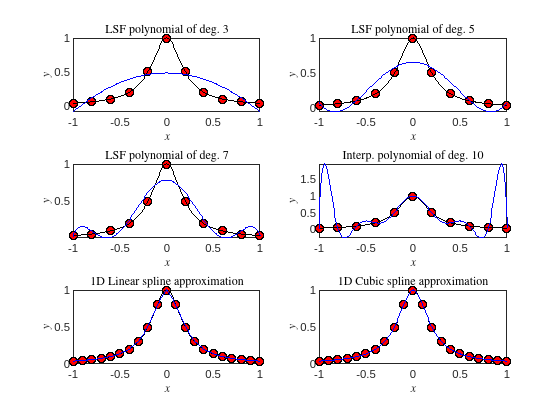

xs = a:0.1:b;
ys = f(xs);
yys = spline(xs,ys,xOrig);
subplot(3,2,6);
plot(xs,ys,'o','Marker','o','MarkerFaceColor','red','MarkerEdgeColor',...
    'black','lineWidth',1)
title('1D Cubic spline approximation','Interpreter','LaTeX') 
hold on
plot(xOrig,yOrig,'-','color','black')
plot(xOrig,yys,'-','color','blue')
xlabel('$x$','Interpreter','LaTeX')
ylabel('$y$','Interpreter','LaTeX')
hold off

## Exercise

Compute the mean and maximum error between the original curve $y=f(x)$ and their approximation according to the polynomial degree for the measure points x=a:0.2:b. Do the computations for degrees $n=3,5,7,10$ . (Use all plotted points, xOrig=a:0.01:b to compute errors).

**Note: **If $a\le x_{1} < x_{2} <\dots < x_{M}\le b$ is a collection of abscisses in the interval $[a,b]$ (for example, the points we've used in these sscript to plot the function,$f(x)$, and the lsf polynomials, $p(x)$) we define the *mean error (*$\epsilon_{\text{{mean}}$) and the *maximum error (*$\epsilon_{\max}$) wrt these points, by:

- Mean error:  $\displaystyle \epsilon_{\text{mean}} := \frac{1}{M}\sum_{i=1}^{M}\left|f(x_{i}) - p(x_{i})\right|$, and

- Max. error: $\displaystyle\epsilon_{\max} := \max_{i=1,\dots,M}\left|f(x_{i})-p(x_{i})\right|$, respectively.

 In particular, if one introduces the vectors $Y = \left(f(x_{1}),\dots,f(x_{M})\right)^{\top}$and $P = \left(p(x_{1}),\dots,p(x_{M})\right)^{\top}$, then $\epsilon_{\max} = \|Y-P\|_{\infty}$. Recall that, by definition, the $\infty$-norm of a vector $v = \left(v_{1},\dots,v_{M}\right)^{\top}\in\mathbb{R}^{M}$is given by $\left\|v\right\|_{\infty} := \max_{i=1,\dots,M}\left|v_{i}\right|$. 

The $\infty$-norm of a vector can be computed in Matlab calling the function `norm,` i.e., the same function as to find the $2$-norm, but adding inf as a second argument. For example:

v = rand(1,5)

v =      7.585428956306361e-02     5.395011866660715e-02     5.307975530089727e-01     7.791672301020112e-01     9.340106842291830e-01



norm2 = sqrt(sum(v.^2)) %2-norm (using definition)

norm2 =      1.330371399853694e+00


norm2 = norm(v)          %2-norm (using Matlab's function norm)

norm2 =      1.330371399853694e+00


norm2 = norm(v,2)        %2-norm (equivalently)

norm2 =      1.330371399853694e+00


normInf = max(abs(v))    %inf-norm (using definition)

normInf =      9.340106842291830e-01


normInf = norm(v,inf)    %inf-norm (usinf Matlab's function norm)

normInf =      9.340106842291830e-01


## Solution

degree = [3,5,7,10];
sz = length(degree);
numPoints = length(xOrig);

%Create a table
T = table('Size',[sz, 3],'VariableTypes',...
     {'uint8','double','double'},...
     'VariableNames',{'Degree','MeanError','MaxError'}); %Matlab > 2007 to work
                                                        
meanErr = zeros(sz,1);
maxErr = zeros(sz,1);

for k = 1:sz  % k takes values 3, 5, 7, 10  
    p = polyfit(x,y,degree(k));
    pxOrig = polyval(p,xOrig);
    %mean error
    meanErr = norm(yOrig-pxOrig,1)/numPoints; 
    %meanErr(k) = sum(abs(yOrig-pxOrig))/numPoints; %alternatively
    %max error
    maxErr = norm(yOrig-pxOrig,inf); 
    %maxErr(k) = max(abs(yOrig-pxOrig)); %alternatively
    T.Degree(k,1) = degree(k);
    T.MeanError(k,1) = meanErr;
    T.MaxError(k,1) = maxErr;
end

format short e
T

T = 4×3 table
    Degree    MeanError      MaxError 
    ______    __________    __________

       3      1.5835e-01    5.1588e-01
       5      1.1186e-01    3.4478e-01
       7      7.9675e-02    2.1539e-01
      10      2.8987e-01    1.9156e+00
